# Labo1B - : Introduction aux signaux et systèmes numériques

clc; clear; close all;

## Réponse temporelle des systèmes numériques (ex1)

### Produit de convolution

On a vu que la réponse temporelle d’un système linéaire causal peut se calculer avec le produit de convolution suivant:


$$y\left\lbrack n\right\rbrack =\sum_{k=0}^{\min \left(n,N-1\right)} h\left\lbrack k\right\rbrack x\left\lbrack n-k\right\rbrack ,\;\;\;\;\;n=0,1,2,3,\ldotp \ldotp \ldotp$$


La fonction *conv* existe bien entendu dans Matlab. Cependant, afin de bien comprendre l’algorithme de convolution, vous créerez votre propre fonction *[yn] = myconv(hn,xn)*. Pour cela : 

- Calculez à la main la convolution entre *xn = [1,2,3,4]* et *hn = [5,6]* ; quelle est la longueur du résultat yn ? 

- Qu’est ce qui change si on augmente la longueur de xn avec des 0 (par exemple, *xn = [1,2,3,4,0,0]*) ? 

- Ecrivez un fichier myconv.m dont la première ligne sera function [yn] = myconv(hn,xn); 

- Définissez les longueurs des signaux dont vous aurez besoin. Écrivez la double boucle for vous permettant de calculer yn(n). Aide : La boucle for interne calcule la somme pour chaque décalage k, la boucle externe calcule la sortie pour chaque indice n du signal. 

- Testez votre fonction avec les signaux définis au point 1. 

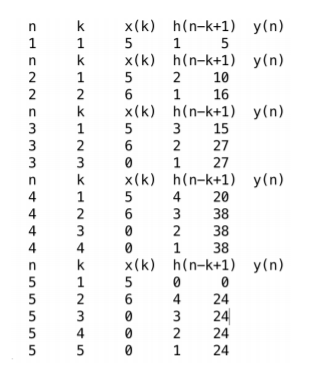                             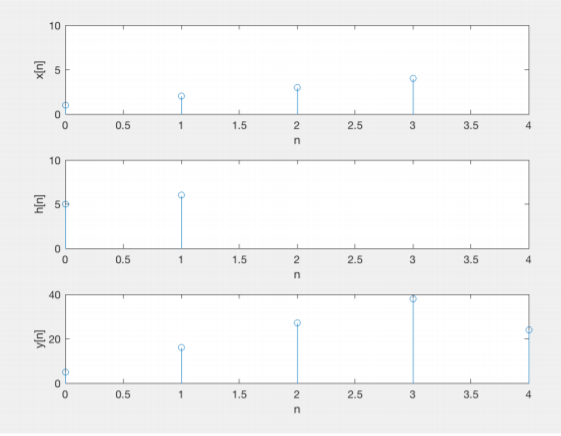

% votre code

## Réponses impulsionnelles et temporelles (ex2)

On désire découvrir le comportement de systèmes décrits par les réponses impulsionnelles suivantes : 

Pour ce faire : 

- Tracez ces réponses impulsionnelles avec *subplot(3,2,k); plot(hkn,’.’) ;* observez et commentez. 

- Dans une nouvelle figure, calculez et tracez leur réponse *yn = conv(xn,hkn)* à un signal carré *xn = [0,ones(1,20),zeros(1,20)]*. 

- Observez et analysez ces réponses ; à quels types de filtres a-t-on affaire ? 

- Quelles sont les longueurs de xn et yn ? Justifiez leur valeur. 

- Que faut-il faire pour que le gain des filtres passe-bas soit égal à 1 ? Pourquoi que les filtres passe-bas??

- On dirait que les filtres PH ont des h[n] avec des valeurs négatives -> faire la somme des éléments ne fonctionne pas

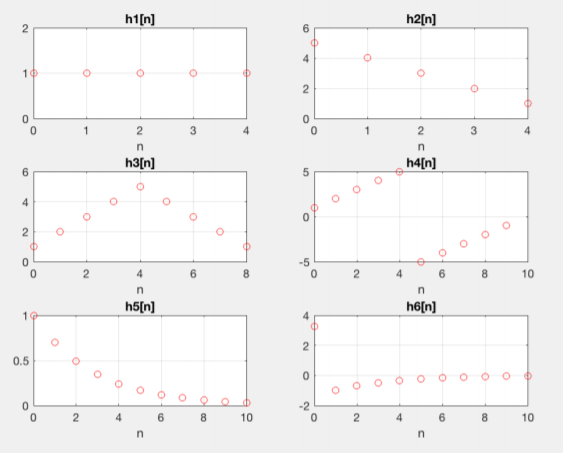   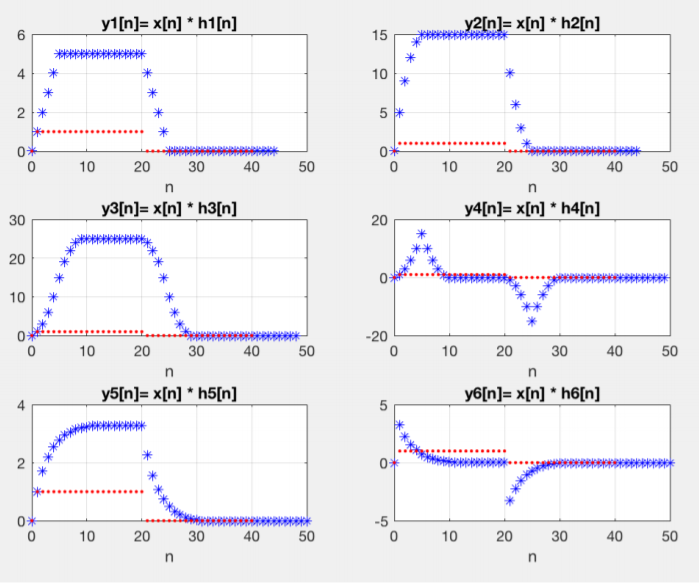

On observe que la réponse du système est symétrique si la réponse impultionnelle est symétrique. 

Filtre passe-bas: les flancs abruptes dans le signal deviennent des trapèzes.

Filtre passe-haut: la composante continue ne se retrouve pas dans la réponse du système

% votre code

### Équations aux différences (ex3)

Un filtre ou système numérique d’ordre 2 est décrit de manière générale par une équation aux différences telle que :


$$a_o y\left\lbrack n\right\rbrack +a_1 y\left\lbrack n-1\right\rbrack +a_2 y\left\lbrack n-2\right\rbrack =b_0 x\left\lbrack n\right\rbrack +b_1 x\left\lbrack n-1\right\rbrack +b_2 x\left\lbrack n-2\right\rbrack$$


- Écrivez une fonction *[yn] = filtre_ed2(b,a,xn)* vous permettant de calculer la réponse temporelle d’un filtre décrit par les vecteurs a et b de longueur 2. 

- Considérant un filtre décrit par *a = [1,-1.4,+0.45]* et *b = [1,2,1]*, calculez ses pôles et ses zéros. 

- Quel sera le comportement transitoire du système ? Que faut-il faire pour que le gain du filtre soit égal à 1 ? 

- Calculez et tracez sa réponse à *xn = [0, ones(1,50)]*. 

- Observez et commentez ; de quel type de filtre s’agit-il ? 

- Répétez les points 2 à 5 lorsque (a) *a = [1,-1.4,+0.7] et b = [1,2,1]; (b) a = [1,-1.4,+0.9] et b = [1,-2,1]; (c) a = [1,-1.4,+0.45] et b = [1,-2,1]; (d) a = [1,-1.4,+0.7] et b = [1,-2,1]; (e) a = [1,-0.7,0] et b = [1,0,0];* 

- Comparez vos résulats avec ceux fournis par la fonction filter(b,a,x) de Matlab.

% votre code

## Effets Audio numériques (ex4)

### Echo

Dans cet effet audio numérique on utilise un retard D supérieur à 50 ms (D est le nombre d’échantillons, pour un retard de 50 ms avec Fs = 8kHz D = 400). L’effet est simplement la somme entre le son original et sa version retardé comme illustré dans la figure suivante. Les deux gains G1 et G2 permettent d'ajuster l’intensité de l’écho par rapport au son original. Les paramètres dans votre code seront ici les gains G1 et G2 ainsi que la duréé D du retard. Ce système fait partie des filtres à réponse impulsionnelle finie (FIR).

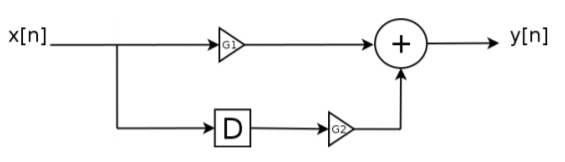

### Réverbération

Dans ce cas l’effet audio est celui d’un écho multiple (itératif) qui s’ajoute au son original. Techniquement ceci est réalisé avec les mêmes fonctions de base que l’écho mais au lieu d’appliquer le retard au signal d’entrée x[n] on va l’appliquer au signal de sortie y[n]. Les paramètres dans votre code seront ici les gains G1 et G2 ainsi que la durée D du retard. Ce système fait partie des filtres à réponse impulsionnelle infinie (IIR).

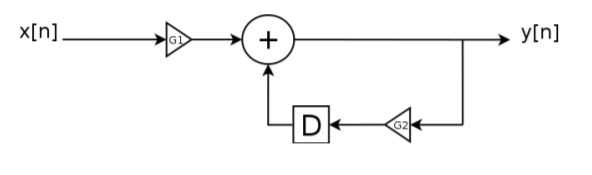

### Travail demandé

- Lisez un fichier de type WAV avec la fonction : *[x, Fs] = audioread(filename)* y est le vecteur contenant les échantillons du signal, et *Fs* la fréquence d’échantillonnage. Une boucle *for* va permettre de parcourir tout le signal échantillon par échantillon. Dans cette boucle la fonction spécifique à un effet audio va être appelée et va prendre un échantillon d’entrée *x[n]* à la fois et calculer l’échantillon de sortie *y[n]*. A la suite de la boucle de traitement on affichera sur un graphique le signal d’entrée et le signal de sortie. On peut également écouter le signal d’entrée et le signal de sortie avec la fonction *soundsc()*.

- Écrivez une fonction *outsample = myecho(insample,G1,G2,D)* permettant de calculer pour un échantillon d’entrée insample l’échantillon de sortie outsample, et les paramètres G1, G2, D. Attention cette fonction doit conserver un tampon de données de D échantillons entre un appel et le suivant. pour ceci utiliser la déclaration de variables locales à la fonction avec la primitive *persistent*, comme dans l’exemple ci dessous. 

- Testez la fonction echo en écoutant le signal de sortie avec un son de votre choix et en faisant varier les gains G1 et G2. Que constatez vous ? Essayez de déterminer quel retard D minimum vous arrivez à percevoir en écoutant le son traité. Que peut- on en conclure ? 

- Ecrire la fonction *outsample = reverberation(insample,G1,G2,D)* de la même manière que pour la fonction écho. 

- Testez la fonction *reverberation()* et déterminer l’effet du gain G2, que peut-on en déduire ?

% votre code